[~,folder,~] = fileparts(pwd);
assert(strcmpi(folder,"defect reconstruction using coil and sensor array"), 'Not in project directory')
addpath('../../DCS_functions')

clear

#### Reconstruction matrix

load('precompute_30x30x2.mat')

lambda = 1e-4;
s_threshold = 5e-6;

n = size(S,2); % number of elements
S = reshape(permute(S,[1 3 2]), [],n);

s = vecnorm(S);
s(s < s_threshold) = 1;
L = diag(s .^ 0.25);

R = (S' * S + L' * L * lambda) \ S';

clear n lambda S_ct

#### Perform reconstruction

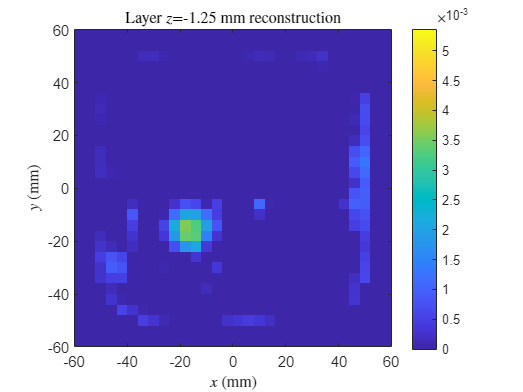

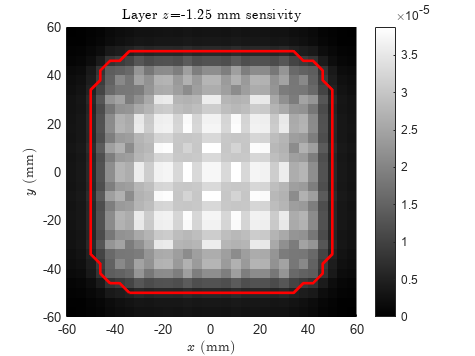

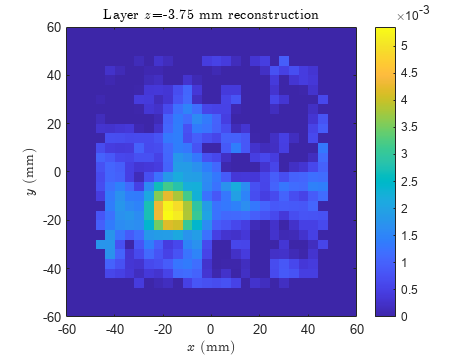

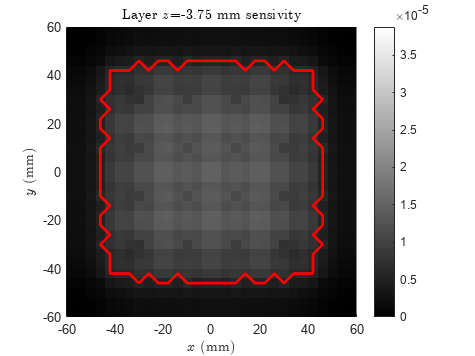

B_bar = readB('DCS_B_uniform.csv');
B_m   = readB('FEM_B_bottom-hole.txt');
delta_B = B_m - B_bar;
delta_B = reshape(delta_B, [],1);
delta_p = real(R * delta_B);

s = vecnorm(S);

layers = unique(elems_center(3,:));
layers = sort(layers, 'descend');
for z = layers
    mask = elems_center(3,:) == z;
    x = elems_center(1,mask) * 1e3;
    y = elems_center(2,mask) * 1e3;
    n_x = length(unique(x));
    x = reshape(x, n_x, []);
    y = reshape(y, n_x, []);

    delta_p_layer = reshape(delta_p(mask), n_x, []);

    figure
    imagesc([min(x) max(x)], [min(y) max(y)], delta_p_layer.', [0 max(delta_p,[],'all')]);
    colorbar;
    title(sprintf('Layer $z$=%.2f mm reconstruction', z*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
    xlim([-60 60])
    ylim([-60 60])
    axis xy square
    
    s_layer = reshape(s(mask), n_x, []);
    B = bwboundaries(s_layer > s_threshold);
    B = (B{1} - n_x/2 - 0.5) * 4;

    figure
    hold on
    imagesc([min(x) max(x)], [min(y) max(y)], s_layer.', [0 max(s,[],'all')]);
    plot(B(:,1), B(:,2), 'r', 'LineWidth',2);
    colormap gray
    colorbar
    title(sprintf('Layer  $z$=%.2f mm sensivity', z*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
    xlim([-60 60])
    ylim([-60 60])
    axis xy square
end


clear layers mask n_x x y z delta_p_layer s_layer

function B = readB(filename)

data = readmatrix(fullfile('Forward_data',filename), 'CommentStyle','%');
if contains(filename, 'DCS', 'IgnoreCase',true)
    B = permute(data, [1 3 2]);
elseif contains(filename, 'FEM', 'IgnoreCase',true)
    B = data(:, 4:end);
    num_sensors = size(B,1);
    B = reshape(B, num_sensors, 3, []);
    B = pagetranspose(B);
    B = reshape(B, num_sensors*3, 1, []);
else
    error('Unknown file formatting')
end

end